%该文件用来绘制影长随一年中每一天的变化
%取一年有365天

n=1:365;%根据自定义函数求得n
phi=((39+54/60+26/3600)/180)*2*pi;%由题，北京纬度为39度54分26秒
t=12;%取北京时间12点作为参考量
st_t=t-8+(116+23/60+29/3600)/15;%根据自定义函数转化为当地标准时间
H=((15*(st_t-12))/180)*2*pi;%H为太阳时角
L=3;%表示直杆长度

l=zeros(1,size(n,2));%用来存储所求的所有影长
for i=1:size(n,2) 
    delte=abs((23.45*sin(2*pi*(284+n(i))/365))/180)*2*pi;%delte为太阳赤纬
    alpha=asin(sin(delte)*sin(phi)+cos(delte)*cos(phi)*cos(H));%alpha为太阳光线的入射角度
    l(1,i)=abs(L/tan(alpha));%l表示此时影长
end
[lmax,indax]=max(l)

lmax =   16.835088382068541


indax =     81


[lmin,indin]=min(l)

lmin =    1.949390483281801


indin =    172


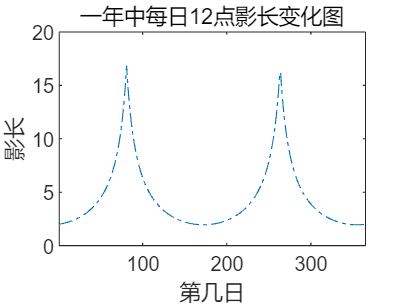

figure(1)
plot(n,l,'-.');
title('一年中每日12点影长变化图');
xlabel('第几日');
ylabel('影长');
xlim([1,365]);